** Definitions**

variance = 100;

state = [0 0]'

state =      0
     0



covarianceMatrix = [variance 0; 0 variance];

**Example #1**

alt = [6.43	1.3	39.43	45.89	41.44	48.7	78.06	80.08	61.77	75.15	110.39	127.83	158.75	156.55	213.32	229.82	262.8	297.57	335.69	367.92	377.19	411.18	460.7	468.39	553.9	583.97	655.15	723.09	736.85	787.22];

acc = [39.81	39.67	39.81	39.84	40.05	39.85	39.78	39.65	39.67	39.78	39.59	39.87	39.85	39.59	39.84	39.9	39.63	39.59	39.76	39.79	39.73	39.93	39.83	39.85	39.94	39.86	39.76	39.86	39.74	39.94];

estimateAlt = zeros(1, length(alt));
velocity = zeros(1, length(alt));

time = zeros(1, length(alt));
prevState = state;
prevCovariance = covarianceMatrix;
for i = 1:length(alt)
    [estimateAlt(i), velocity(i), prevState, prevCovariance] = kalmanFilter(acc(i), alt(i), prevState, prevCovariance, 0.25, 0.1);
    time(i) = i*0.25;
end

velEnd = 30* time(end);

Tvelocity = linspace(0, velEnd, 30);
Tposition = Tvelocity + (30*0.5) .* time.^2

Tposition = 1.0e+03 *

    0.0009    0.0115    0.0240    0.0383    0.0545    0.0725    0.0925    0.1143    0.1380    0.1636    0.1910    0.2203    0.2515    0.2846    0.3196    0.3564    0.3951    0.4356    0.4781    0.5224    0.5686    0.6167    0.6666    0.7184    0.7721    0.8277    0.8852    0.9445    1.0057    1.0688


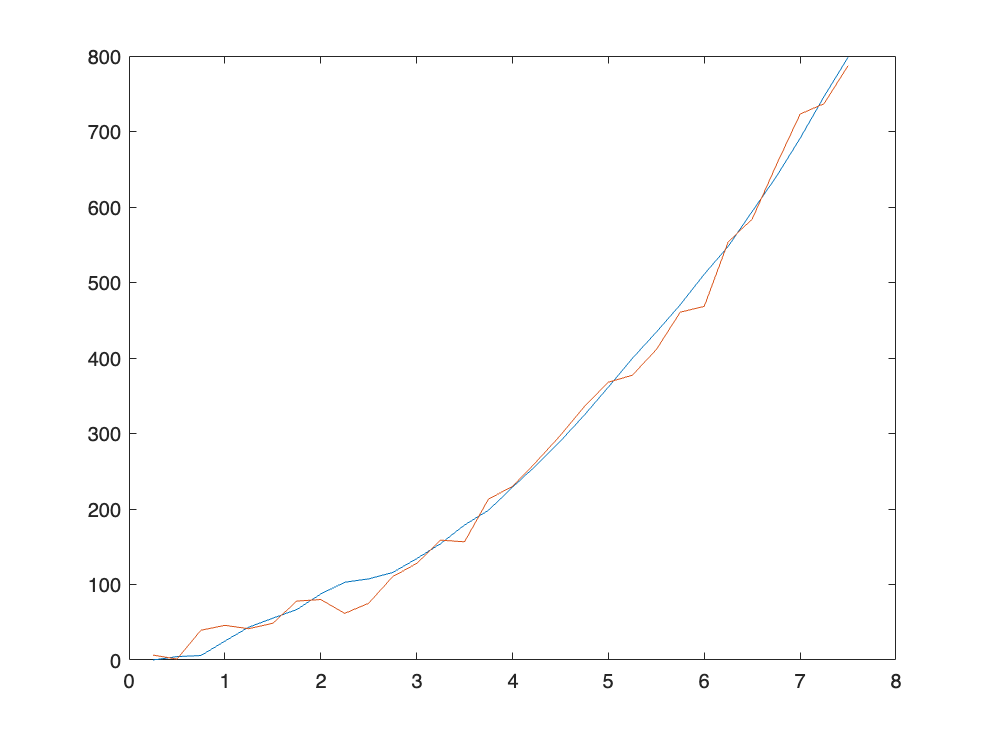

figure(1)
plot(time, estimateAlt)
hold on
plot(time, alt)

hold off

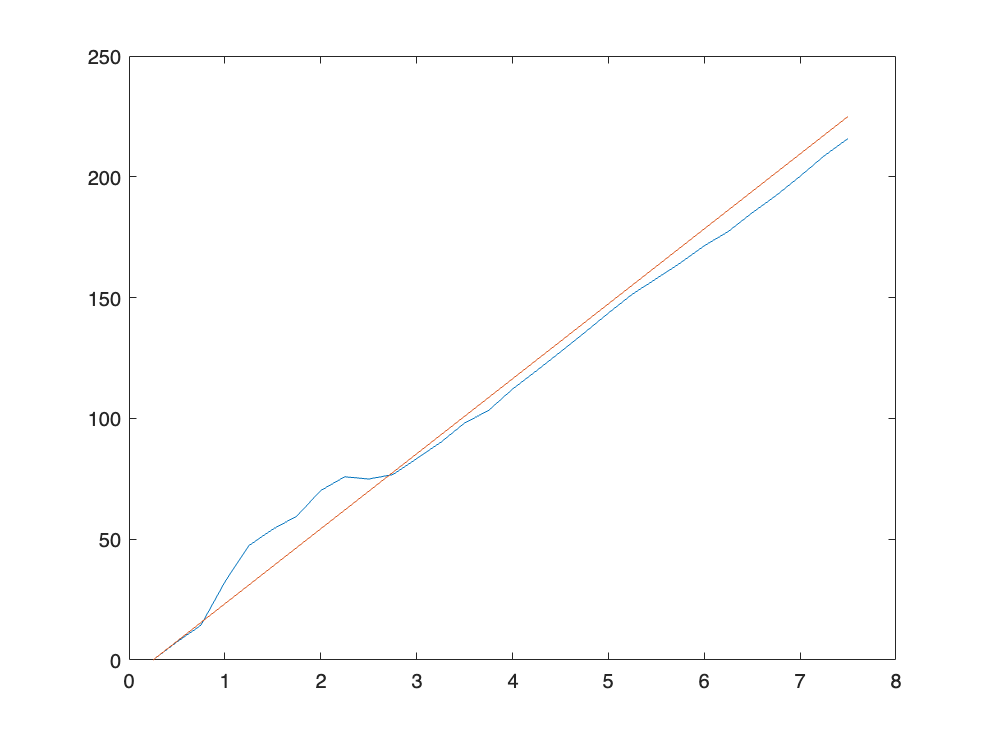

figure(2)
plot(time, velocity)
hold on
plot(time, Tvelocity)
hold off

**Using Karman Mini Launch Data**

LaunchData = readmatrix("/Users/nikilesh/Documents/WORK/Sunride/MatlabTesting/launch_1.csv");
yAccel = LaunchData(:, 3);
BaroHeight = LaunchData(:, 19);
BaroHeight = BaroHeight - BaroHeight(1);
timeSeconds = LaunchData(:, 20);
timeSeconds = (timeSeconds - timeSeconds(1))/1000;
filteredHeight = zeros(length(yAccel), 1);
Fvelocity = zeros(length(yAccel), 1);

xGyro = LaunchData(:,6);

tic
for i = 1:length(yAccel)
    if i == 1
        [filteredHeight(i), Fvelocity(i), prevState, prevCovariance] = kalmanFilter(yAccel(i), BaroHeight(i), state, covarianceMatrix, 0.003, 28.16);
    else
        [filteredHeight(i), Fvelocity(i), prevState, prevCovariance] = kalmanFilter(yAccel(i), BaroHeight(i), prevState, prevCovariance, 0.001, 28.16);
    end
end
toc

Elapsed time is 0.165143 seconds.


disp(filteredHeight)

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0679
    0.1260
    0.1762
    0.2201
    0.2588
    0.2931
    0.3238
    0.3515
    0.3764
    0.3992
    0.4199
    0.4389
    0.4564
    0.4725
    0.4875
    0.5014
    0.5144
    0.4967
    0.4801
    0.4645
    0.4499
    0.4362
    0.4232
    0.4109
    0.3993
    0.3882
    0.3777
    0.3678
    0.3583
    0.3492
    0.3405
    0.3323
    0.3243
    0.3167
    0.3094
    0.3024
    0.3051
    0.3077
    0.3102
    0.3126
    0.3149
    0.3172
    0.3193
    0.3214
    0.3234
    0.3254
    0.3273
    0.3292
    0.3310
    0.3327
    0.3344
    0.3361
    0.3377
    0.3392
    0.3336
    0.3281
    0.3228
    0.3176
    0.3125
    0.3075
    0.3026
    0.2978
    0.2932
    0.2886
    0.2841
    0.2797
    0.2754
    0.2712
    0.2671
    0.2630
    0.2590
    0.2551
    0.2513
    0.2475
    0.2498
    0.2521
    0.2543
    0.2566
    0.2587

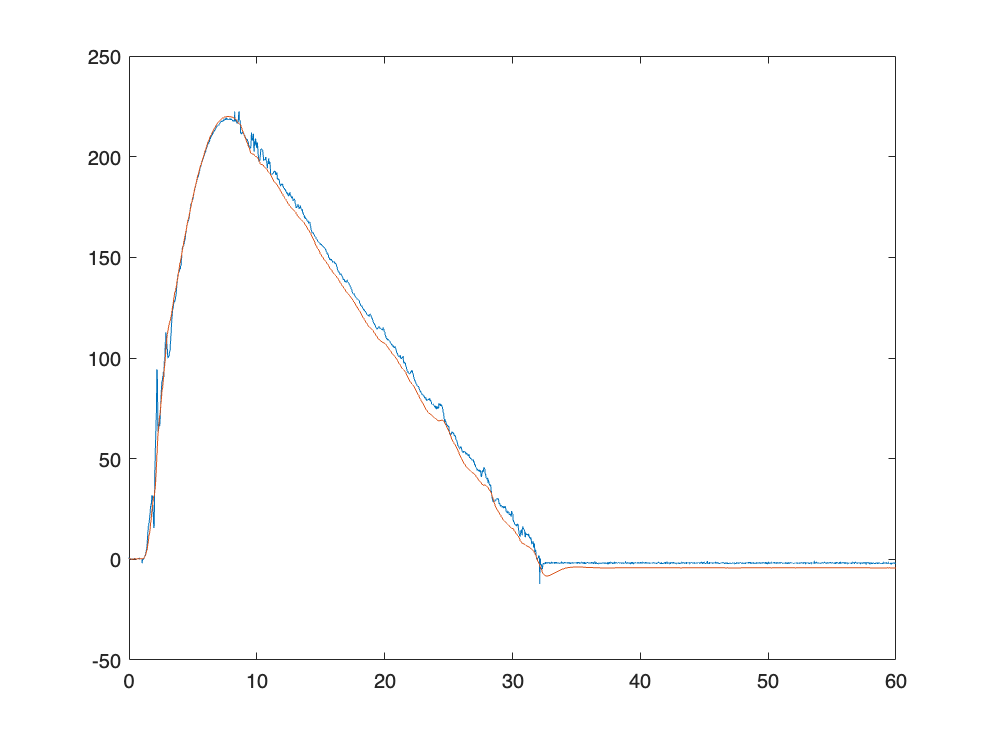

figure(3)
plot(timeSeconds, BaroHeight)
hold on
plot(timeSeconds, filteredHeight)
hold off

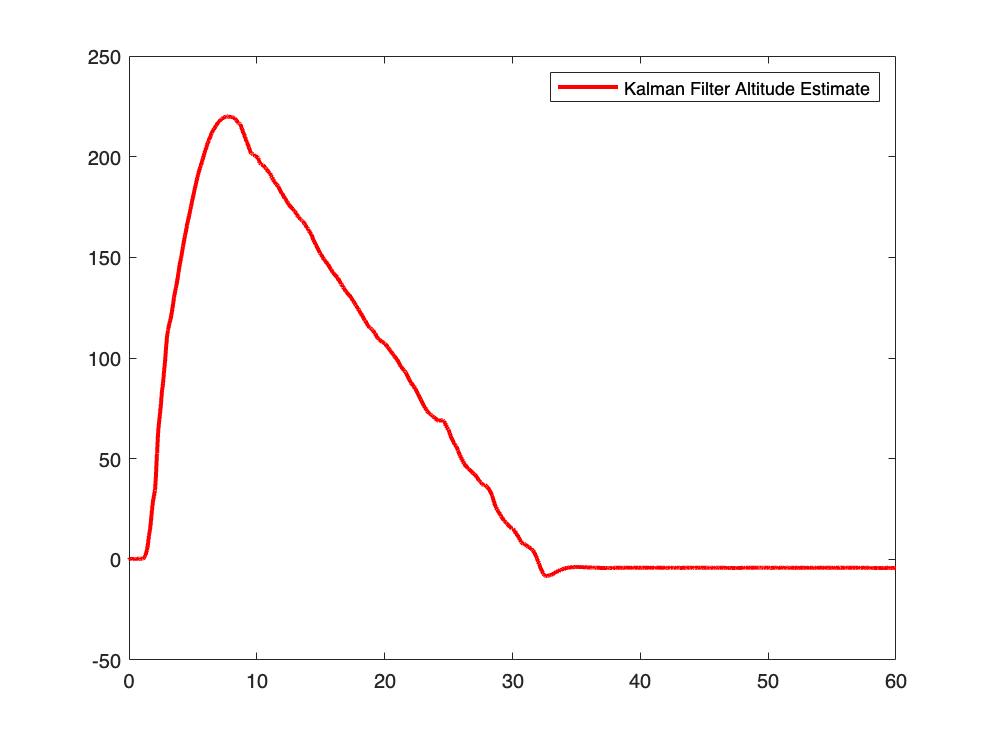


figure(4)
plot(timeSeconds, filteredHeight, LineWidth=2,Color=[1 0 0])
legend("Kalman Filter Altitude Estimate")

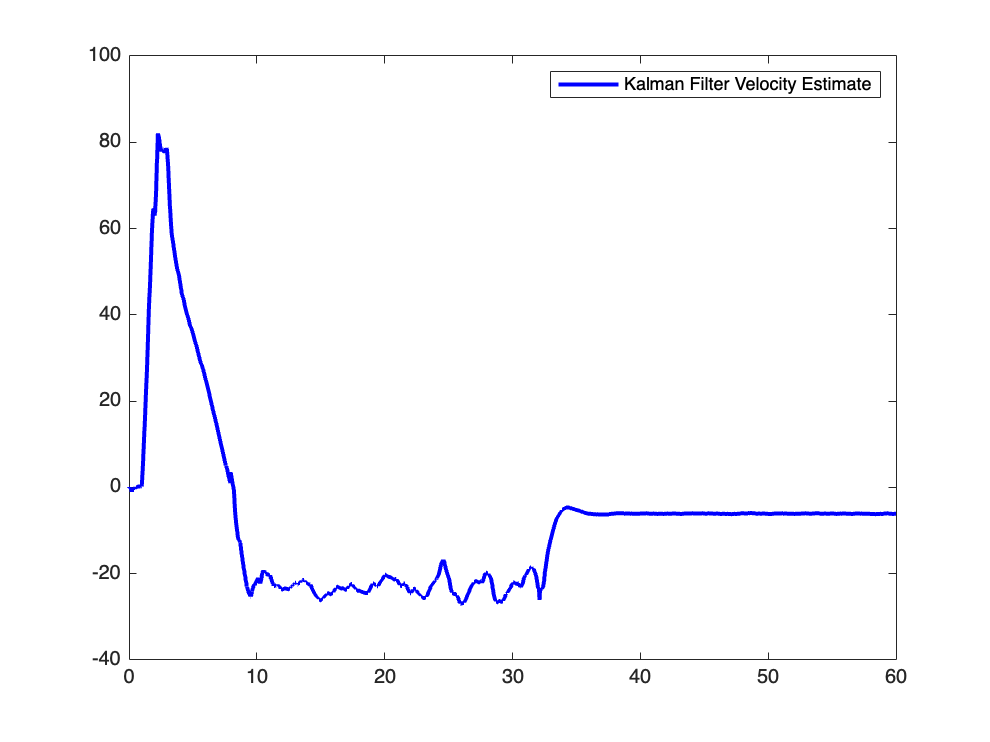


figure(5)
plot(timeSeconds, Fvelocity, LineWidth=2, Color=[0 0 1])
legend("Kalman Filter Velocity Estimate")

**Further Analysis**

dPos_dt = diff(xGyro) ./ diff(timeSeconds)

dPos_dt = 1.0e+06 *

    0.0003
   -0.0004
    0.0009
    0.0013
   -0.0018
    0.0005
    0.0008
   -0.0008
   -0.0022
    0.0013


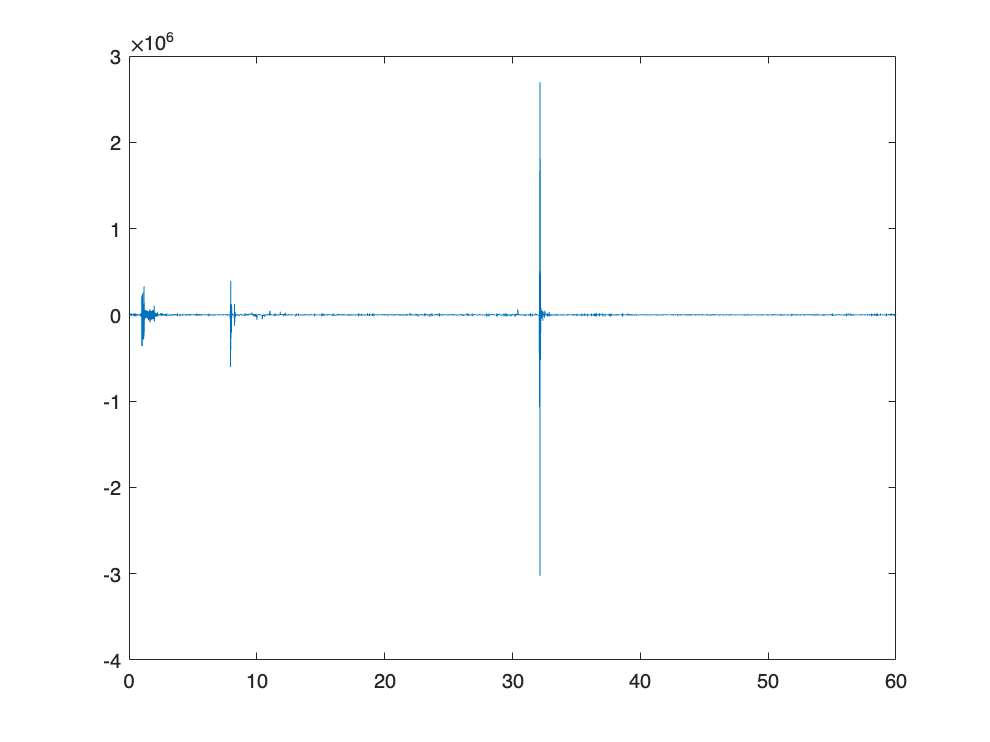

figure(6)
plot(timeSeconds(1:end-1), dPos_dt)


VelAnalysis = fft(xGyro)

VelAnalysis = 1.0e+06 *

  -0.0476 + 0.0000i
  -2.6561 - 0.4074i
  -2.2482 + 1.5992i
  -0.9209 + 2.7215i
   0.5716 + 1.9193i
   0.9938 + 1.6628i
   1.3389 + 0.4298i
   1.0461 + 0.3303i
   0.8508 - 0.4659i
   0.4238 - 0.3014i


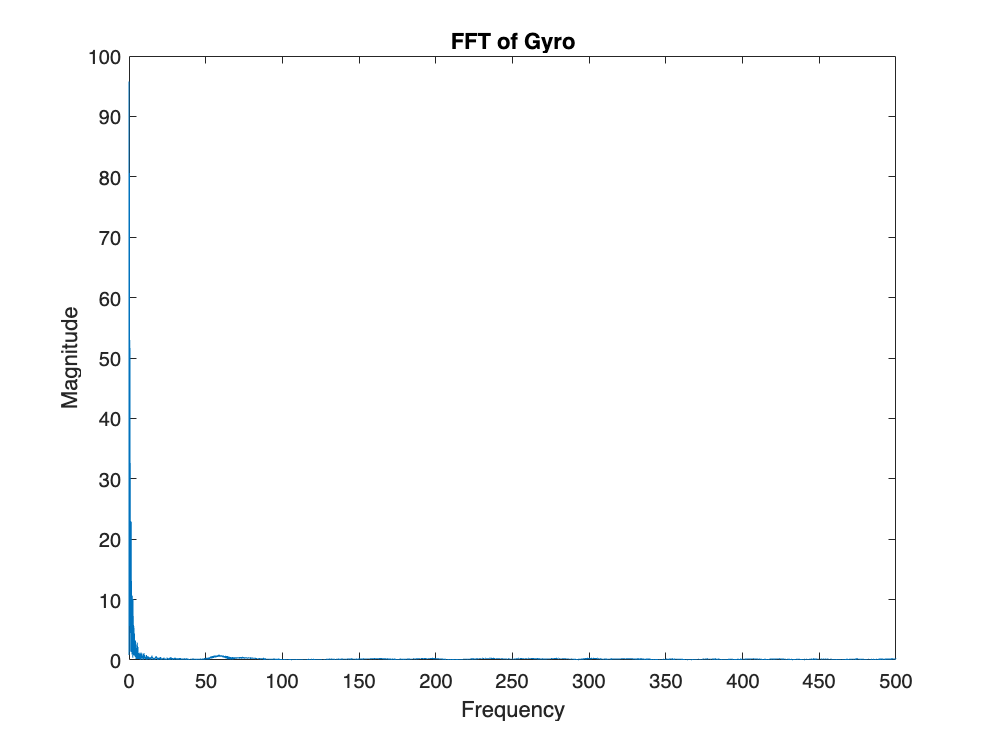

L = 59.998*1000;
T = 0.001;
timeVectorFFT = (0:L-1)*T;
Fs = 1/T;
P2 = abs(VelAnalysis/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure(7)
plot(f,P1) 
title('FFT of Gyro')
xlabel('Frequency')
ylabel('Magnitude')

**Prediction step**

function [alt, vel, state, covarianceMatrix] = kalmanFilter(accel, baroAlt, state, covarianceMatrix, dt, STDacc)
%predicts the next state of the system
    g= 9.81;
    delta_t = dt;
    accelSTD = STDacc;
    
    % Transition [1 delta]       Contol [0.5*delta^2]
    %            [0     1]              [    delta  ]

    stateTransitionMatrix = [1 delta_t; 0 1];
    controlMatrix = [0.5*(delta_t^2) delta_t]';
    controlInput = (accel-g);
    % Process Noise [ t^4/4  t^3/2]     
    %               [ t^2/2  t    ]
    processNoise = [delta_t^4/4 delta_t^3/2; delta_t^2/2 delta_t^2] * accelSTD^2;
    observationMatrix = [1 0];
    measCovariance = 80.67;

    meas = baroAlt;
   
    alt = state(1,1);
    vel = state(2,1);

    innovationCovarianceMatrix = observationMatrix * covarianceMatrix * observationMatrix' + measCovariance;

    kalmanGain = covarianceMatrix * observationMatrix' / innovationCovarianceMatrix;
    state = state + kalmanGain * (meas - observationMatrix * state);
    covarianceMatrix = (eye(2) - kalmanGain * observationMatrix) * covarianceMatrix * (eye(2) - kalmanGain * observationMatrix)' + kalmanGain * measCovariance * kalmanGain';

    state = stateTransitionMatrix * state + controlMatrix * controlInput;
    covarianceMatrix = stateTransitionMatrix * covarianceMatrix * stateTransitionMatrix' + processNoise;  
end
